# Piecewise 

syms x
f = piecewise(x < 0, x^2, 0 <= x <= 1, x, x > 1, 2 - x);

disp(f)

$$\left\{ \begin{array}{cl} x^{2} & \text{ if }x<0\\ x & \text{ if }x\in \left[0,1\right]\\ 2-x & \text{ if }1<x \end{array}\right.$$

syms g_min g_max     positive real
syms alpha   positive real 
syms phi     real % do not specify phi as positive 

% assume(alpha>0 & alpha<=pi)

T = 2*pi;

digits(4)

% alpha is pole arc 
% beta is the non-pole arc 
poleArc = alpha;
midArc = (T - 2*poleArc) / 2; 

magneticRef = 0;

## Compare Symbolic Expression with Symbolic Function 

### Symbolic Expression & Shifted 

% assume(phi > 0)
g_phi_se = piecewise( ...
    (sym(magneticRef) < phi) & (phi < poleArc), g_min, ...
    (poleArc <= phi) & (phi < poleArc + midArc), g_max ...
)

$$g\_phi\_se = \left\{ \begin{array}{cl} g_{\min} & \text{ if }\varphi <\alpha \wedge 0<\varphi \\ g_{\max} & \text{ if }\varphi <\pi \wedge \alpha \leq \varphi \end{array}\right.$$


% int(g_phi_se, phi, [0 T/2])

$$ans = \left\{ \begin{array}{cl} \pi \,g_{\min} & \text{ if }\alpha =\pi \\ \alpha \,g_{\min}-g_{\max}\,\left(\alpha -\pi \right) & \text{ if }\alpha <\pi \end{array}\right.$$

g_shifted_se = subs(g_phi_se, [phi alpha], [phi-T pi/3])

$$g\_shifted\_se = \left\{ \begin{array}{cl} g_{\min} & \text{ if }\varphi \in \left(2\,\pi ,\frac{7\,\pi }{3}\right)\\ g_{\max} & \text{ if }\varphi \in \left[\frac{7\,\pi }{3},3\,\pi \right) \end{array}\right.$$

### Symbolic Function & Shifted 

g_phi_sf(phi) = piecewise( ...
    (sym(magneticRef) < phi) & (phi < poleArc), g_min, ...
    (poleArc <= phi) & (phi < poleArc + midArc), g_max ...
)

$$g\_phi\_sf(phi) = \left\{ \begin{array}{cl} g_{\min} & \text{ if }\varphi <\alpha \wedge 0<\varphi \\ g_{\max} & \text{ if }\varphi <\pi \wedge \alpha \leq \varphi \end{array}\right.$$

g_shifted_sf(phi) = subs(g_phi_sf(phi-T), alpha, pi/3)

$$g\_shifted\_sf(phi) = \left\{ \begin{array}{cl} g_{\min} & \text{ if }\varphi \in \left(2\,\pi ,\frac{7\,\pi }{3}\right)\\ g_{\max} & \text{ if }\varphi \in \left[\frac{7\,\pi }{3},3\,\pi \right) \end{array}\right.$$

G_MIN = 0.5;
G_MAX = 0.8;

figure 
fplot(subs(g_shifted_se, [g_min g_max], [0.5 0.8]), [0 2*T], ...
      "LineWidth", 1.2)
hold on
fplot(subs(g_shifted_sf, [g_min g_max], [0.5 0.8]), [0 2*T], "o", ...
      "Color", "r")
hold off 
ylim([0 1])
grid on 

### Conclusion

Although the type of `g_phi_sf` and `g_phi_se` are different, their results look identical.

## Compare (a <= phi < b, "Continuous") with ((phi >= a) & (phi < b), "Discrete")

g_phi_continuous(phi) = piecewise( ...
    sym(magneticRef) <= phi < poleArc, g_min, ...
    poleArc <= phi < poleArc + midArc, g_max)

$$g\_phi\_continuous(phi) = \left\{ \begin{array}{cl} g_{\min} & \text{ if }\varphi <\alpha \wedge 0\leq \varphi \\ g_{\max} & \text{ if }\varphi <\pi \wedge \alpha \leq \varphi \end{array}\right.$$

g_phi_discrete(phi) = piecewise( ...
    (sym(magneticRef) < phi) & (phi < poleArc), g_min, ...
    (poleArc <= phi) & (phi < poleArc + midArc), g_max)

$$g\_phi\_discrete(phi) = \left\{ \begin{array}{cl} g_{\min} & \text{ if }\varphi <\alpha \wedge 0<\varphi \\ g_{\max} & \text{ if }\varphi <\pi \wedge \alpha \leq \varphi \end{array}\right.$$

### Conclusion

They are effectively the same. However, 

% Uncomment the following code to see error message 
% g_phi_discrete(phi) = piecewise( ...
%     (sym(magneticRef) < phi) & (phi < poleArc), g_min, ...
%     (poleArc <= phi) & (phi < poleArc + midArc), g_max ...
%     (phi > poleArc + midArc) & (phi < 2 * poleArc + midArc), g_min, ...
%     (2 * poleArc + midArc <= phi) & (phi <= 2 * poleArc + 2 * midArc), g_max ...
% )

g_phi_continuous(phi) = piecewise( ...
    sym(magneticRef) <= phi < poleArc, g_min, ...
    poleArc <= phi < poleArc + midArc, g_max, ...
    poleArc + midArc <= phi < 2 * poleArc + midArc, g_min, ...
    2 * poleArc + midArc <= phi <= 2 * poleArc + 2 * midArc, g_max)

$$g\_phi\_continuous(phi) = \left\{ \begin{array}{cl} g_{\min} & \text{ if }\varphi <\alpha \wedge 0\leq \varphi \\ g_{\max} & \text{ if }\varphi <\pi \wedge \alpha \leq \varphi \\ g_{\min} & \text{ if }\pi \leq \varphi \wedge \varphi <\alpha +\pi \\ g_{\max} & \text{ if }\varphi \leq 2\,\pi \wedge \alpha +\pi \leq \varphi \end{array}\right.$$

It seems that only the continuous treatment is more robust. 

## Right Extend Symbolic Piecewise Function

g_phi(phi) = g_phi_continuous(phi)

$$g\_phi(phi) = \left\{ \begin{array}{cl} g_{\min} & \text{ if }\varphi <\alpha \wedge 0\leq \varphi \\ g_{\max} & \text{ if }\varphi <\pi \wedge \alpha \leq \varphi \\ g_{\min} & \text{ if }\pi \leq \varphi \wedge \varphi <\alpha +\pi \\ g_{\max} & \text{ if }\varphi \leq 2\,\pi \wedge \alpha +\pi \leq \varphi \end{array}\right.$$


g_phi_ext(phi) = piecewise( ...
    phi >= T, g_phi(phi-T), ...
    g_phi(phi) ...
)

$$g\_phi\_ext(phi) = \left\{ \begin{array}{cl} g_{\min} & \text{ if }\varphi <\alpha +2\,\pi \wedge 2\,\pi \leq \varphi \\ g_{\max} & \text{ if }\alpha +2\,\pi \leq \varphi \wedge \varphi <3\,\pi \\ g_{\min} & \text{ if }\varphi <\alpha +3\,\pi \wedge 3\,\pi \leq \varphi \\ g_{\max} & \text{ if }\alpha +3\,\pi \leq \varphi \wedge \varphi \leq 4\,\pi \\ g_{\min} & \text{ if }\varphi <\alpha \wedge 0\leq \varphi \\ g_{\max} & \text{ if }\varphi <\pi \wedge \alpha \leq \varphi \\ g_{\min} & \text{ if }\pi \leq \varphi \wedge \varphi <\alpha +\pi \\ g_{\max} & \text{ if }\varphi \leq 2\,\pi \wedge \alpha +\pi \leq \varphi \end{array}\right.$$

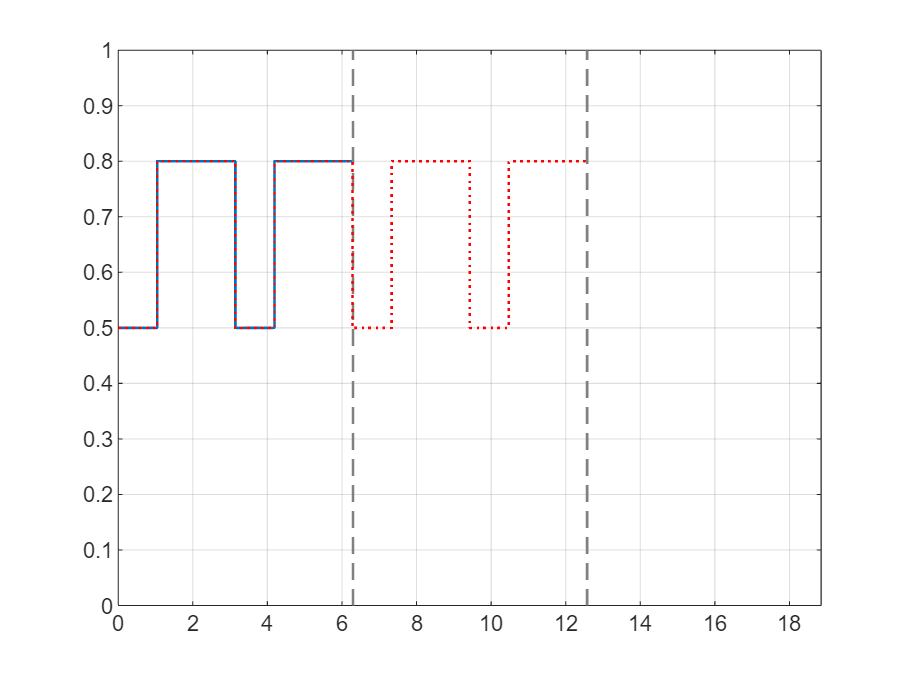

figure 
fplot(subs(g_phi, [alpha g_min g_max], [pi/3 0.5 0.8]), [0 3*T], ...
      "LineWidth", 1.2)
hold on
fplot(subs(g_phi_ext, [alpha g_min g_max], [pi/3 0.5 0.8]), [0 3*T], ...
      "Color", "r", ...
      "LineStyle",":", ...
      "LineWidth", 1.2 ...
      )
hold off 
ylim([0 1])
grid on 

Note that `g_phi` (blue) is defined within [0, T], whereas `g_phi_ext` (red dot) extended from `g_phi` is now covering [0, 2*T], with [2*T, 3*T] being empty as this range is underdefined, even though it is asked for plot in fplot(). 

## Left and Right Extend Symbolic Piecewise Function

g_phi_LR_ext(phi) = piecewise( ...
    -2*T <= phi < -T, g_phi(phi+2*T), ...
    -T <= phi < 0, g_phi(phi+T), ...
    0 <= phi < T, g_phi(phi), ...
    T <= phi < 2*T, g_phi(phi-T) ...
)

$$g\_phi\_LR\_ext(phi) = \left\{ \begin{array}{cl} g_{\min} & \text{ if }\varphi \in \left[-4\,\pi ,-2\,\pi \right)\wedge \varphi +4\,\pi <\alpha \\ g_{\max} & \text{ if }\alpha \leq \varphi +4\,\pi \wedge \varphi <-3\,\pi \\ g_{\min} & \text{ if }\varphi \in \left[-3\,\pi ,-2\,\pi \right)\wedge \varphi +3\,\pi <\alpha \\ g_{\max} & \text{ if }\alpha \leq \varphi +3\,\pi \wedge \varphi <-2\,\pi \\ g_{\min} & \text{ if }\varphi +2\,\pi <\alpha \wedge \varphi \in \left[-2\,\pi ,0\right)\\ g_{\max} & \text{ if }\alpha \leq \varphi +2\,\pi \wedge \varphi <-\pi \\ g_{\min} & \text{ if }\varphi \in \left[-\pi ,0\right)\wedge \varphi +\pi <\alpha \\ g_{\max} & \text{ if }\varphi <0\wedge \alpha \leq \varphi +\pi \\ g_{\min} & \text{ if }\varphi <\alpha \wedge \varphi \in \left[0,2\,\pi \right)\\ g_{\max} & \text{ if }\varphi <\pi \wedge \alpha \leq \varphi \\ g_{\min} & \text{ if }\varphi \in \left[\pi ,2\,\pi \right)\wedge \varphi <\alpha +\pi \\ g_{\max} & \text{ if }\varphi <2\,\pi \wedge \alpha +\pi \leq \varphi \\ g_{\min} & \text{ if }\varphi \in \left[2\,\pi ,4\,\pi \right)\wedge \varphi <\alpha +2\,\pi \\ g_{\max} & \text{ if }\alpha +2\,\pi \leq \varphi \wedge \varphi <3\,\pi \\ g_{\min} & \text{ if }\varphi \in \left[3\,\pi ,4\,\pi \right)\wedge \varphi <\alpha +3\,\pi \\ g_{\max} & \text{ if }\alpha +3\,\pi \leq \varphi \wedge \varphi <4\,\pi \end{array}\right.$$

figure 
fplot(subs(g_phi, [alpha g_min g_max], [pi/3 0.5 0.8]), [-2*T 3*T], ...
      "LineWidth", 1.2)
hold on
fplot(subs(g_phi_LR_ext, [alpha g_min g_max], [pi/3 0.5 0.8]), [-2*T 3*T], ...
      "Color", "r", ...
      "LineStyle",":", ...
      "LineWidth", 1.2 ...
      )
hold off 
ylim([0 1])
grid on 

Looks great—it works perfectly as expected!

## Last Thing: Make It an Even Function

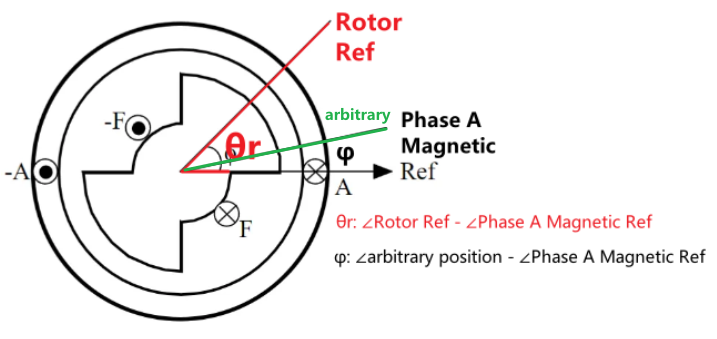

% Eyeball a position where g_phi reaches its maximum position 
% record the angle difference between that position and original 
% left/right shift g_phi by that angle difference 
shiftedAngle = alpha + midArc/2; 
g_phi_even(phi) = simplify(g_phi_LR_ext(phi+shiftedAngle))

$$g\_phi\_even(phi) = \left\{ \begin{array}{cl} g_{\min} & \text{ if }\frac{\alpha }{2}+\varphi +\frac{\pi }{2}\in \left[-4\,\pi ,-2\,\pi \right)\wedge 2\,\varphi +9\,\pi <\alpha \\ g_{\max} & \text{ if }\alpha +2\,\varphi <-7\,\pi \wedge \alpha \leq 2\,\varphi +9\,\pi \\ g_{\min} & \text{ if }\frac{\alpha }{2}+\varphi +\frac{\pi }{2}\in \left[-3\,\pi ,-2\,\pi \right)\wedge 2\,\varphi +7\,\pi <\alpha \\ g_{\max} & \text{ if }\alpha +2\,\varphi <-5\,\pi \wedge \alpha \leq 2\,\varphi +7\,\pi \\ g_{\min} & \text{ if }\frac{\alpha }{2}+\varphi +\frac{\pi }{2}\in \left[-2\,\pi ,0\right)\wedge 2\,\varphi +5\,\pi <\alpha \\ g_{\max} & \text{ if }\alpha +2\,\varphi <-3\,\pi \wedge \alpha \leq 2\,\varphi +5\,\pi \\ g_{\min} & \text{ if }\frac{\alpha }{2}+\varphi +\frac{\pi }{2}\in \left[-\pi ,0\right)\wedge 2\,\varphi +3\,\pi <\alpha \\ g_{\max} & \text{ if }\alpha +2\,\varphi <-\pi \wedge \alpha \leq 2\,\varphi +3\,\pi \\ g_{\min} & \text{ if }2\,\varphi +\pi <\alpha \wedge \frac{\alpha }{2}+\varphi +\frac{\pi }{2}\in \left[0,2\,\pi \right)\\ g_{\max} & \text{ if }\alpha +2\,\varphi <\pi \wedge \alpha \leq 2\,\varphi +\pi \\ g_{\min} & \text{ if }2\,\varphi <\alpha +\pi \wedge \frac{\alpha }{2}+\varphi +\frac{\pi }{2}\in \left[\pi ,2\,\pi \right)\\ g_{\max} & \text{ if }\alpha +\pi \leq 2\,\varphi \wedge \alpha +2\,\varphi <3\,\pi \\ g_{\min} & \text{ if }\frac{\alpha }{2}+\varphi +\frac{\pi }{2}\in \left[2\,\pi ,4\,\pi \right)\wedge 2\,\varphi <\alpha +3\,\pi \\ g_{\max} & \text{ if }\alpha +2\,\varphi <5\,\pi \wedge \alpha +3\,\pi \leq 2\,\varphi \\ g_{\min} & \text{ if }\frac{\alpha }{2}+\varphi +\frac{\pi }{2}\in \left[3\,\pi ,4\,\pi \right)\wedge 2\,\varphi <\alpha +5\,\pi \\ g_{\max} & \text{ if }\alpha +2\,\varphi <7\,\pi \wedge \alpha +5\,\pi \leq 2\,\varphi \end{array}\right.$$


figure 
fplot(subs(g_phi_LR_ext, [alpha g_min g_max], [pi/3 0.5 0.8]), [-2*T 2*T])
hold on 
fplot(subs(g_phi_even, [alpha g_min g_max], [pi/3 0.5 0.8]), [-2*T 2*T], ...
    "LineWidth", 1.2)
hold off 
ylim([0 1])
grid on 